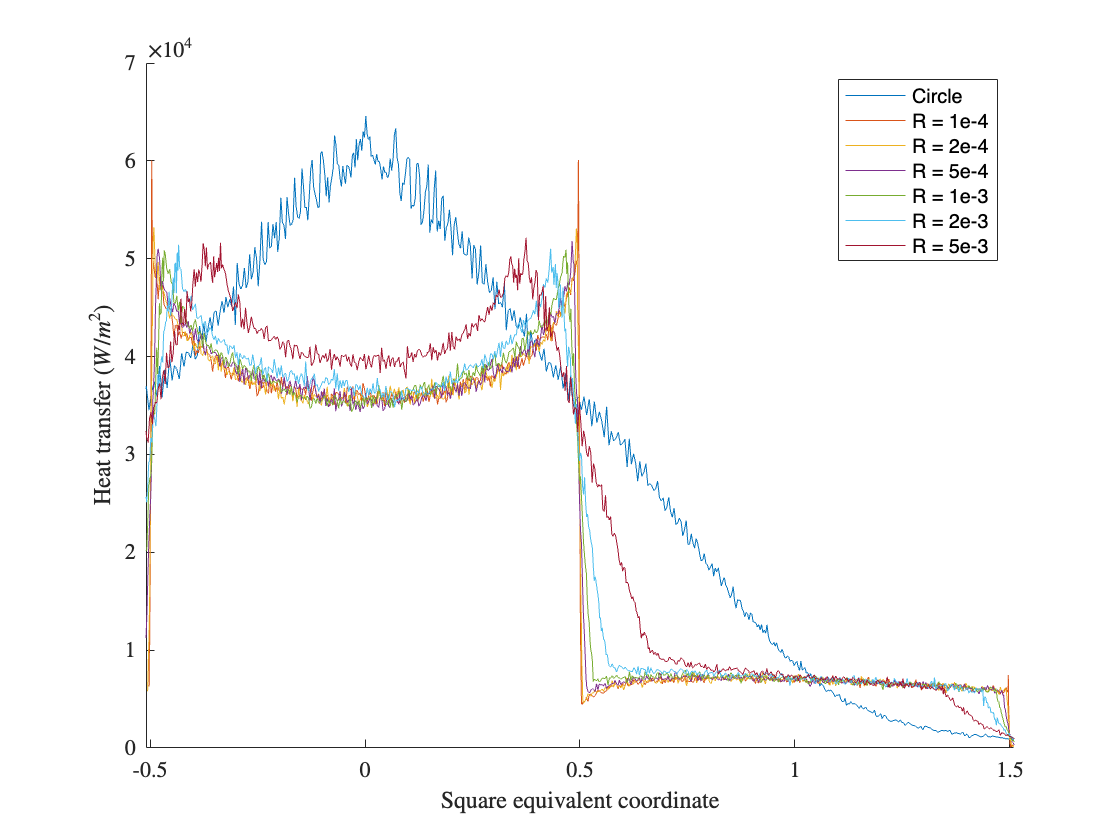

clear

sp=170;
u=1655;
cp=1.4;
tw=300;
t0=273;
H0=cp*t0+u^2/2;
hw=cp*tw;
rho=1.727e-4;
stden=rho * u * (H0 - hw);

circle = readmatrix('./radius_results/circle.txt');
circle = sortrows(circle(8:end,1:10),1);
circle(:,11) = circle(:,10)./mean(circle(sp-5:sp+5,10));
circle(:,12) = circle(:,10)./stden;
circle(:,13:14)=coords('./radius_results/geometry/circle.txt');

r1eminus4 = readmatrix('./radius_results/r1e-4.txt');
r1eminus4 = sortrows(r1eminus4(8:end,1:10),1);
r1eminus4(:,11) = r1eminus4(:,10)./mean(r1eminus4(sp-5:sp+5,10));
r1eminus4(:,12) = r1eminus4(:,10)./stden;
r1eminus4(:,13:14)=coords('./radius_results/geometry/r1e-4.txt');
r1eminus4=r1eminus4(r1eminus4(:,14)<=1.7,:);

r2eminus4 = readmatrix('./radius_results/r2e-4.txt');
r2eminus4 = sortrows(r2eminus4(8:end,1:10),1);
r2eminus4(:,11) = r2eminus4(:,10)./mean(r2eminus4(sp-5:sp+5,10));
r2eminus4(:,12) = r2eminus4(:,10)./stden;
r2eminus4(:,13:14)=coords('./radius_results/geometry/r2e-4.txt');
r2eminus4=r2eminus4(r2eminus4(:,14)<=1.7,:);

r5eminus4 = readmatrix('./radius_results/r5e-4.txt');
r5eminus4 = sortrows(r5eminus4(8:end,1:10),1);
r5eminus4(:,11) = r5eminus4(:,10)./mean(r5eminus4(sp-5:sp+5,10));
r5eminus4(:,12) = r5eminus4(:,10)./stden;
r5eminus4(:,13:14)=coords('./radius_results/geometry/r5e-4.txt');
r5eminus4=r5eminus4(r5eminus4(:,14)<=1.7,:);

r1eminus3 = readmatrix('./radius_results/r1e-3.txt');
r1eminus3 = sortrows(r1eminus3(8:end,1:10),1);
r1eminus3(:,11) = r1eminus3(:,10)./mean(r1eminus3(sp-5:sp+5,10));
r1eminus3(:,12) = r1eminus3(:,10)./stden;
r1eminus3(:,13:14)=coords('./radius_results/geometry/r1e-3.txt');
r1eminus3=r1eminus3(r1eminus3(:,14)<=1.7,:);

r2eminus3 = readmatrix('./radius_results/r2e-3.txt');
r2eminus3 = sortrows(r2eminus3(8:end,1:10),1);
r2eminus3(:,11) = r2eminus3(:,10)./mean(r2eminus3(sp-5:sp+5,10));
r2eminus3(:,12) = r2eminus3(:,10)./stden;
r2eminus3(:,13:14)=coords('./radius_results/geometry/r2e-3.txt');
r2eminus3=r2eminus3(r2eminus3(:,14)<=1.7,:);

r5eminus3 = readmatrix('./radius_results/r5e-3.txt');
r5eminus3 = sortrows(r5eminus3(8:end,1:10),1);
r5eminus3(:,11) = r5eminus3(:,10)./mean(r5eminus3(sp-5:sp+5,10));
r5eminus3(:,12) = r5eminus3(:,10)./stden;
r5eminus3(:,13:14)=coords('./radius_results/geometry/r5e-3.txt');
r5eminus3=r5eminus3(r5eminus3(:,14)<=1.7,:);


fig1=figure;
hold on
plot(circle(:,14),circle(:,10))
plot(r1eminus4(:,14),r1eminus4(:,10))
plot(r2eminus4(:,14),r2eminus4(:,10))
plot(r5eminus4(:,14),r5eminus4(:,10))
plot(r1eminus3(:,14),r1eminus3(:,10))
plot(r2eminus3(:,14),r2eminus3(:,10))
plot(r5eminus3(:,14),r5eminus3(:,10))
legend('Circle','R = 1e-4','R = 2e-4','R = 5e-4','R = 1e-3','R = 2e-3','R = 5e-3')
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Heat transfer ($W / m^2$)','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
exportgraphics(fig1,'../Images/4. Results/Radius/htsec.pdf','ContentType','vector');



% figure
% hold on
% %plot(coords(:,2),circle(:,11))
% plot(r1eminus4(:,14),r1eminus4(:,11))
% plot(r2eminus4(:,14),r2eminus4(:,11))
% plot(r5eminus4(:,14),r5eminus4(:,11))
% plot(r1eminus3(:,14),r1eminus3(:,11))
% plot(r2eminus3(:,14),r2eminus3(:,11))
% plot(r5eminus3(:,14),r5eminus3(:,11))
% legend('R = 1e-4','R = 2e-4','R = 5e-4','R = 1e-3','R = 2e-3','R = 5e-3')
% xlabel('z/L')
% ylabel('Normalised heat transfer')
% xlim([-0.51, 1.51])
% title('Normalised heat transfer vs z/L')


% figure
% hold on
% plot(coords(:,2),circle(:,12))
% plot(r1eminus4(:,14),r1eminus4(:,12))
% plot(r2eminus4(:,14),r2eminus4(:,12))
% plot(r5eminus4(:,14),r5eminus4(:,12))
% plot(r1eminus3(:,14),r1eminus3(:,12))
% plot(r2eminus3(:,14),r2eminus3(:,12))
% plot(r5eminus3(:,14),r5eminus3(:,12))
% legend('R = 1e-4','R = 2e-4','R = 5e-4','R = 1e-3','R = 2e-3','R = 5e-3')
% xlabel('z/L')
% ylabel('Equivalent square coordinate')
% xlim([-0.51, 1.51])
% title('Modified Stanton number vs equivalent square coordinate')

